clear all;

dt= 0.02; % stepwise
t= (0:dt:15)'; % total time
u_steer= deg2rad(0);
state0= [0; 0 ; 0; 0];
ds=1;

[states, f_dri, burn] = EngineModel(state0, u_steer, t, dt, ds);


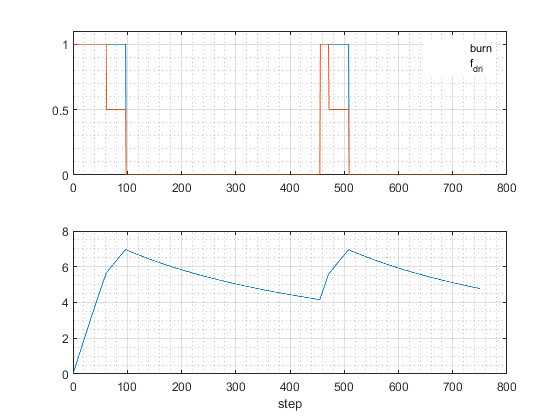

close all;

figure();
subplot(2,1,1)
plot(burn)
hold on;
plot(f_dri)
hold off;
grid on; grid minor;
legend('burn', 'f_{dri}')
ylim([0, 1.1])

subplot(2,1,2)
plot(states(4,:))
grid on; grid minor;
xlabel("step")